load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(A.longitude, A.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

% Seleccionar datos en el mediterráneo
Mrows = A(A.longitude > -13, :);

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(Mrows.longitude, Mrows.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

% Seleccionar solo las filas que sean medidas de equilibrador
MrowsEqu = Mrows(Mrows.Type == "EQU", :);
MrowsEqu.DiffTSGint = MrowsEqu.TEMP - MrowsEqu.IntakeTemp;

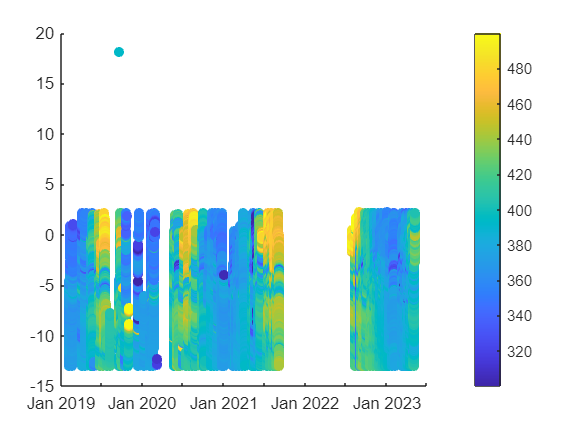

scatter(MrowsEqu.Date, MrowsEqu.longitude, [], MrowsEqu.fCO2sw, "filled")
colorbar;

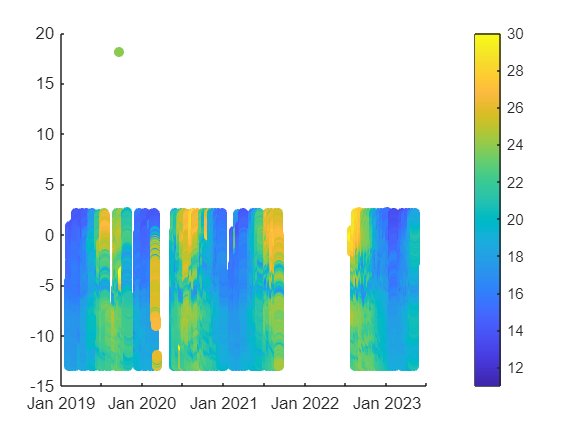

scatter(MrowsEqu.Date, MrowsEqu.longitude, [], MrowsEqu.IntakeTemp, "filled")
colorbar;

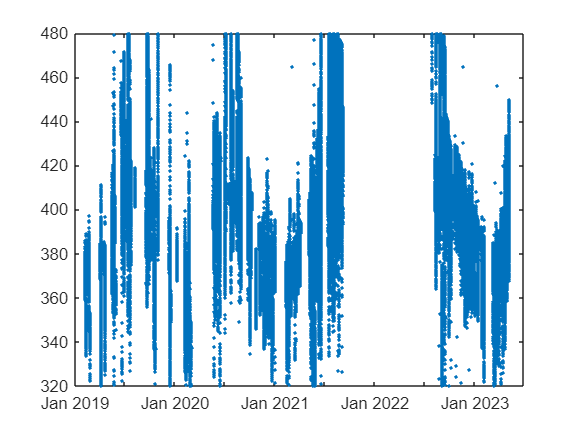

plot(MrowsEqu.Date, MrowsEqu.fCO2sw, ".")

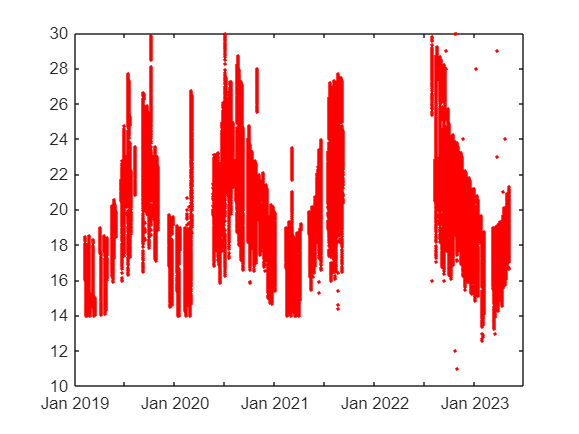

plot(MrowsEqu.Date, MrowsEqu.IntakeTemp, ".r")

% Hallar datos malos de fCO2
badCO2 = find(MrowsEqu.fCO2sw > 480| MrowsEqu.fCO2sw < 320);
badTemp = find(MrowsEqu.IntakeTemp > 30 | MrowsEqu.IntakeTemp < 10);

% Eliminar malas medidas de fCO2 y Temperatura
MrowsEqu.fCO2sw(badCO2) = NaN;
MrowsEqu.IntakeTemp(badTemp) = NaN;

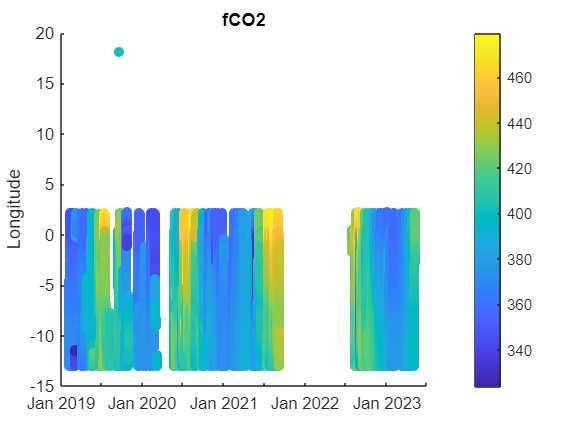

scatter(MrowsEqu1.Date, MrowsEqu1.longitude, [], MrowsEqu1.fCO2sw, "filled")
colorbar;
ylabel("Longitude")
title("fCO2")

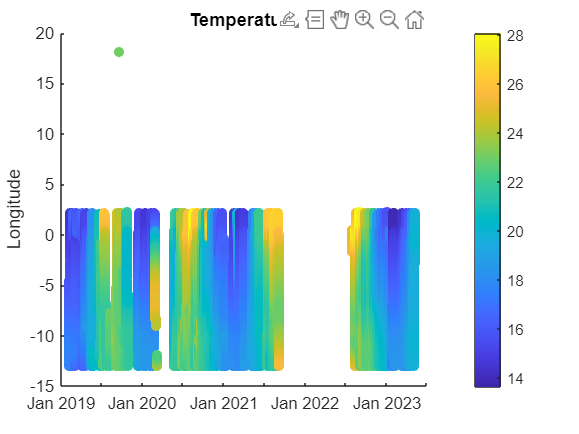

scatter(MrowsEqu1.Date, MrowsEqu1.longitude, [], MrowsEqu1.IntakeTemp, "filled")
colorbar;
ylabel("Longitude")
title("Temperature")

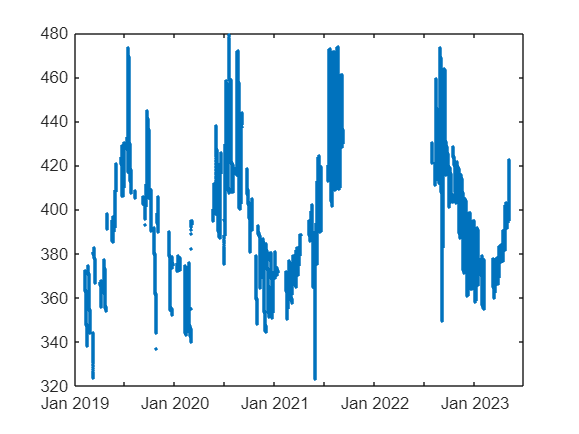

plot(MrowsEqu1.Date, MrowsEqu1.fCO2sw, ".")

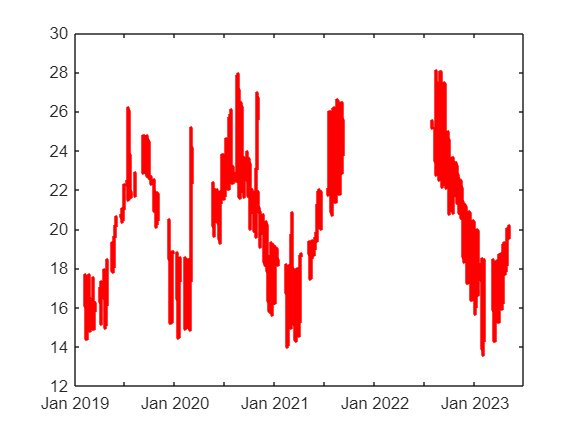

plot(MrowsEqu1.Date, MrowsEqu1.IntakeTemp, ".r")

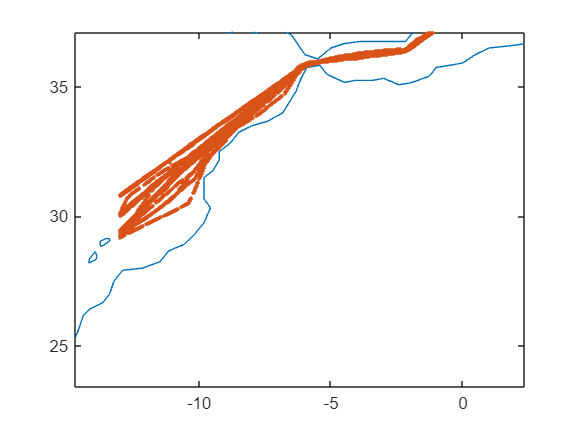

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(MrowsEqu1.longitude, MrowsEqu1.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

MrowsEqu1.latitude(MrowsEqu1.latitude > 90)= NaN;

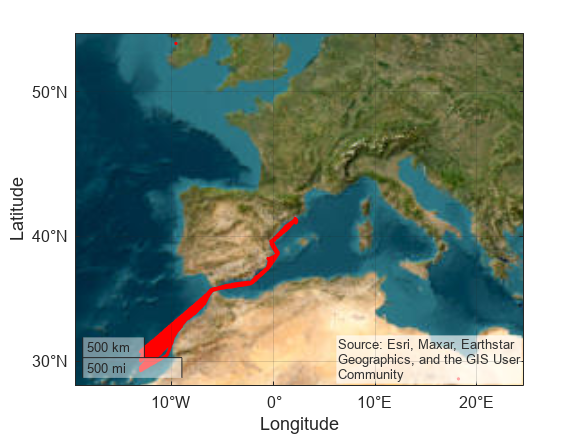

geoplot(MrowsEqu1.latitude, MrowsEqu1.longitude, "r.")

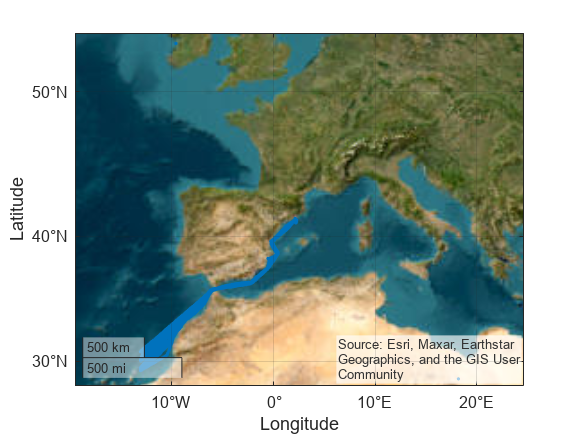

geobasemap satellite

MrowsEqu1.YearFraction = 2019+(MrowsEqu1.JulianDate-43466)./365.25;

m1 = MrowsEqu1(MrowsEqu1.longitude < -11.62 & MrowsEqu1.longitude > -11.72, :);
m2 = MrowsEqu1(MrowsEqu1.longitude < -10.01 & MrowsEqu1.longitude > -10.11, :);
m3 = MrowsEqu1(MrowsEqu1.longitude < -8.39 & MrowsEqu1.longitude > -8.49, :);
m4 = MrowsEqu1(MrowsEqu1.longitude < -6.89 & MrowsEqu1.longitude > -6.99, :);
m5 = MrowsEqu1(MrowsEqu1.longitude < -4.95 & MrowsEqu1.longitude > -5.05, :);
m6 = MrowsEqu1(MrowsEqu1.longitude < -3.75 & MrowsEqu1.longitude > -3.85, :);
m7 = MrowsEqu1(MrowsEqu1.longitude < -1.71 & MrowsEqu1.longitude > -1.81, :);
m8 = MrowsEqu1(MrowsEqu1.longitude < -0.04 & MrowsEqu1.longitude > -0.14 & MrowsEqu1.latitude < 38.3, :);

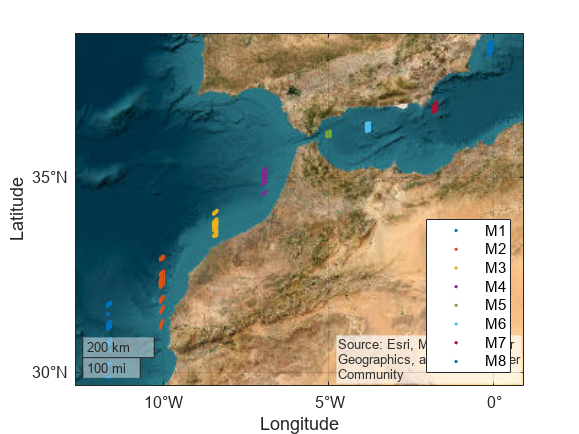


% plot(coastlon, coastlat)
% hold on
geoplot(m1.latitude, m1.longitude, ".")
hold on
geoplot(m2.latitude, m2.longitude, ".")
hold on
geoplot(m3.latitude, m3.longitude, ".")
hold on
geoplot(m4.latitude, m4.longitude, ".")
hold on
geoplot(m5.latitude, m5.longitude, ".")
hold on
geoplot(m6.latitude, m6.longitude, ".")
hold on
geoplot(m7.latitude, m7.longitude, ".")
hold on
geoplot(m8.latitude, m8.longitude, ".")
hold off
% xlim([-20 5])
% ylim([25 45])
legend(["M1", "M2", "M3", "M4", "M5", "M6", "M7", "M8"], "Location","southeast")

geobasemap satellite

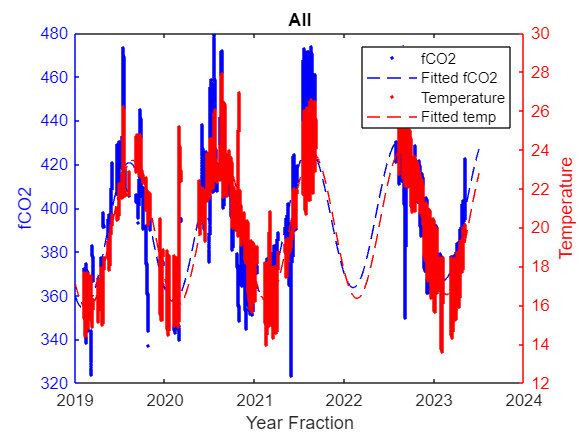

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(MrowsEqu1.YearFraction, MrowsEqu1.fCO2sw, "b.")
title("All")
hold on
plot(fitAll, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(MrowsEqu1.YearFraction, MrowsEqu1.IntakeTemp, ".r")
hold on
plot(fitAllt, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

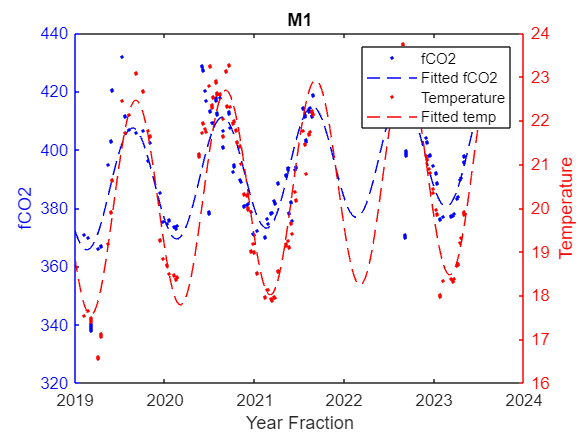

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m1.YearFraction, m1.fCO2sw, "b.")
title("M1")
hold on
plot(fitM1, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m1.YearFraction, m1.IntakeTemp, ".r")
hold on
plot(fitM1t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

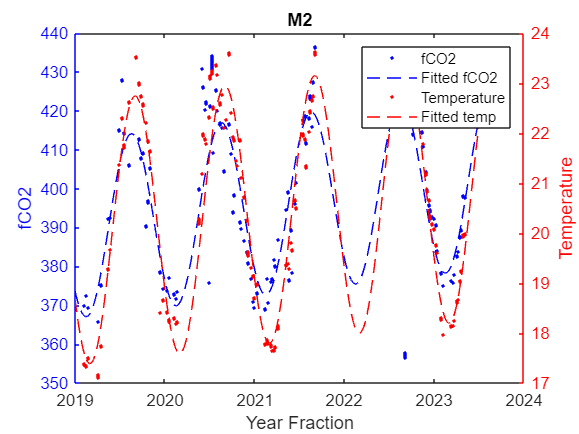

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m2.YearFraction, m2.fCO2sw, "b.")
hold on
plot(fitM2, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m2.YearFraction, m2.IntakeTemp, ".r")
title("M2")
hold on
plot(fitM2t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

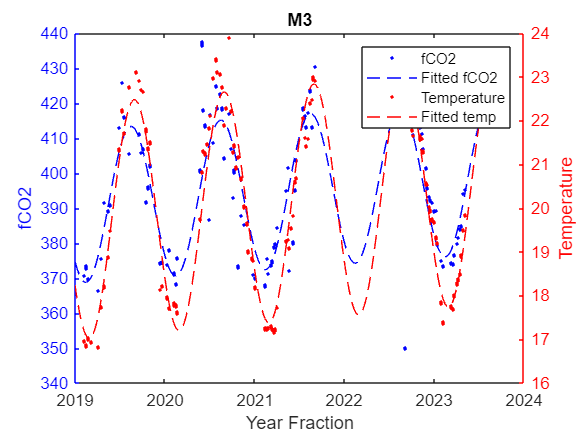

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m3.YearFraction, m3.fCO2sw, "b.")
hold on
plot(fitM3, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m3.YearFraction, m3.IntakeTemp, ".r")
title("M3")
hold on
plot(fitM3t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

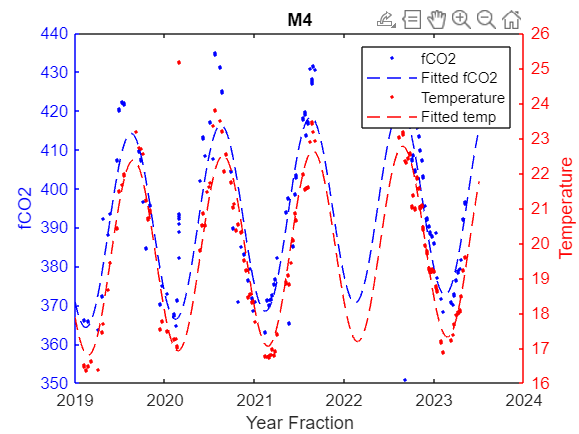

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m4.YearFraction, m4.fCO2sw, "b.")
hold on
plot(fitM4, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m4.YearFraction, m4.IntakeTemp, ".r")
title("M4")
hold on
plot(fitM4t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

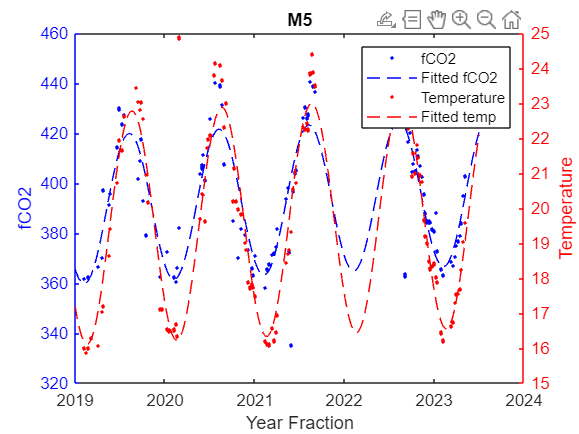

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m5.YearFraction, m5.fCO2sw, "b.")
hold on
plot(fitM5, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m5.YearFraction, m5.IntakeTemp, ".r")
title("M5")
hold on
plot(fitM5t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

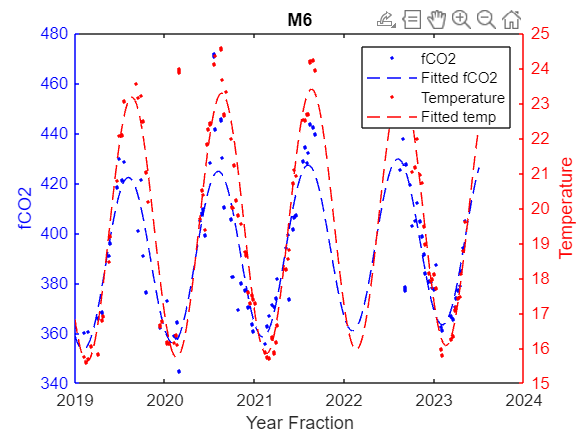

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m6.YearFraction, m6.fCO2sw, "b.")
hold on
plot(fitM6, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m6.YearFraction, m6.IntakeTemp, ".r")
title("M6")
hold on
plot(fitM6t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

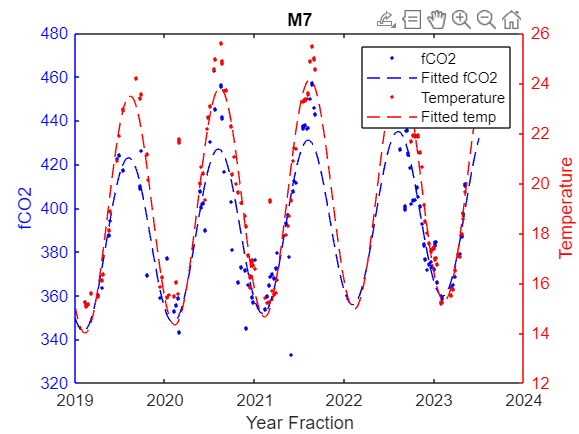

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m7.YearFraction, m7.fCO2sw, "b.")
hold on
plot(fitM7, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m7.YearFraction, m7.IntakeTemp, ".r")
title("M7")
hold on
plot(fitM7t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

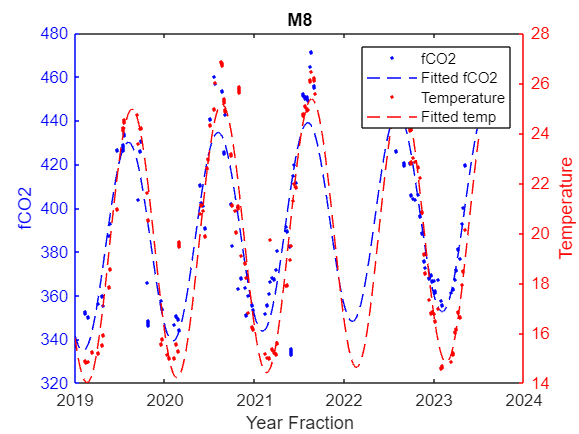

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m8.YearFraction, m8.fCO2sw, "b.")
hold on
plot(fitM8, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m8.YearFraction, m8.IntakeTemp, ".r")
title("M8")
hold on
plot(fitM8t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")